% paths
path = ("C:\Users\BrainMaker\commsubspace\hash");
addpath(path)

addpath(genpath('utils')); % all folders in utils added, including semedo code

% load
load("Megatable.mat");

% query from the folder
%  key = hash; % to examine the current result
key = "f1876f1";
key = "5295fea";

cd(path)
filename = strcat(key,".mat");
load(key+".mat");

Figure 2A: Cofiring in source and target

Figure 2B: Prediction Performance

Figure 4A/B: Results from rank regress

Figure 4C: How optimal number of predicitive dimensions compare between hpc and pfc

% basic structures and stats

% Patterns = table2array(queryresult(1,"Patterntable"));
% Patterns = reshape(table2array(Patterns), [10,2,4]);

if Option.sourceArea == "CA1"
    source = "hpc";
    target = "pfc";
    hpc = 1;
    pfc = 2;
else
    source = "pfc";
    target = "hpc";
    hpc = 2;
    pfc = 1;
end

[nPartitions, nDirections, nPatterns] = size(Patterns);
nPatterns = 3; % single control

% Options = table2array(queryresult(1,"Optiontable"));
nSource = size(Patterns(10,2,1).X_source,1);
nTarget = size(Patterns(10,2,1).X_target,1);
patternnames = ["theta", "delta", "ripples"];

## Figure 2

#### A: How pairs of neuron in source/target co-fire

path2 = "C:\Users\BrainMaker\MATLAB Drive\Shared";
cd(path2)
load("cofiring.mat");

numPairsPerPattern = (nSource+nTarget)^2 - nSource^2 - nTarget^2;

% hetroregion: target and source different, homoregion: target and source
% same
withpfc_pairs = zeros(nPatterns, numPairsPerPattern);
withhpc_pairs = zeros(nPatterns, numPairsPerPattern);

all_pairs_withpfc = [];
all_pairs_withhpc = [];

mean_corrwithpfc = [];
mean_corrwithhpc = [];

mean_withhpccorr_pattern = zeros(1,nPatterns);
mean_withpfccorr_pattern = zeros(1,nPatterns);

std_corrwithhpc = [];
std_corrwithpfc = [];


for p = 1:10
    for i = 1:nPatterns
        curr_source = Patterns(p,1,i).X_source';
        
        curr_HPC = Patterns(p,hpc,i).X_target';
        curr_PFC = Patterns(p,pfc,i).X_target';
        
        linearized_withhpc = plots.calculatePatternCofiring(curr_source, curr_HPC);
        linearized_withpfc = plots.calculatePatternCofiring(curr_source, curr_PFC);
        
        all_pairs_withhpc = [all_pairs_withhpc, linearized_withhpc];
        all_pairs_withpfc = [all_pairs_withpfc, linearized_withpfc];
        
        withpfc_pairs(i,:) = linearized_withpfc;
        withhpc_pairs(i,:) = linearized_withhpc;
        
        mean_withhpccorr_pattern(i) = mean(linearized_withhpc(~isnan(linearized_withhpc)));
        mean_withpfccorr_pattern(i) = mean(linearized_withpfc(~isnan(linearized_withpfc)));
    end
    cur_mean_withhpc = mean(all_pairs_withhpc(~isnan(all_pairs_withhpc)));
    cur_std_withhpc = std(all_pairs_withhpc(~isnan(all_pairs_withhpc)));
    
    cur_mean_withpfc = mean(all_pairs_withpfc(~isnan(all_pairs_withpfc)));
    cur_std_withpfc = std(all_pairs_withpfc(~isnan(all_pairs_withpfc)));
    
    mean_corrwithhpc = [mean_corrwithhpc, cur_mean_withhpc];
    mean_corrwithpfc = [mean_corrwithpfc, cur_mean_withpfc];
    
    std_corrwithhpc = [std_corrwithhpc, cur_mean_withhpc];
    std_corrwithpfc = [std_corrwithpfc, cur_mean_withpfc];
    
end
% hh_pairs_patterns = hh_pairs_patterns(~all(isnan(hh_pairs_patterns), 2))
% hh_pairs_patterns(~isnan(hh_pairs_patterns))
% mean_patternCofiring = mean(hh_pairs_patterns,2);



The co-firing of hpc and pfc neurons during different activity patterns, with average plotted

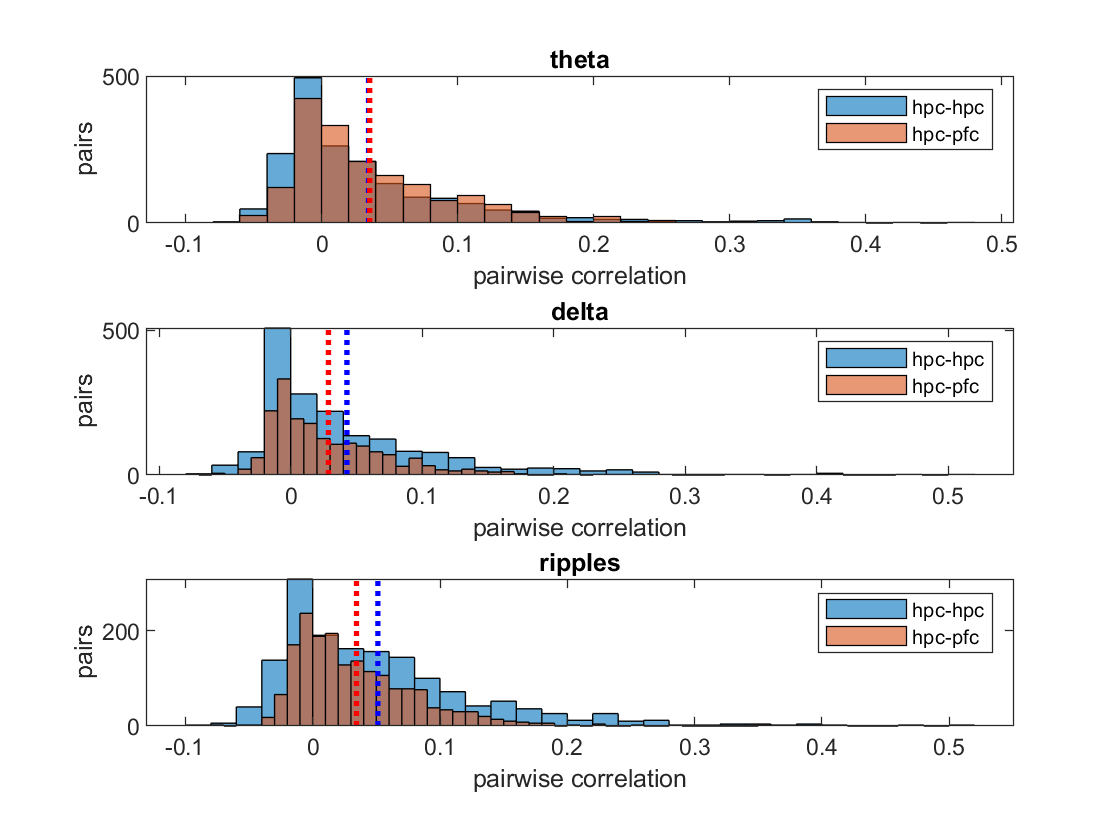

figure(499)
clf
h_corrdiff = zeros(1,nPatterns);
p_corrdiff = zeros(1,nPatterns);
for i = 1:3
    subplot(3,1,i)
    cofiring_hh = histogram(withhpc_pairs(i,:));
    hold on
    cofiring_hp = histogram(withpfc_pairs(i,:));

    title(patternnames(i))
    ylabel("pairs")
    
    hold on
    avg_hh=line([mean_withhpccorr_pattern(i),mean_withhpccorr_pattern(i)],[0 max(cofiring_hh.Values)]);
    avg_hh.LineStyle = ':'; % Make line dotted
    avg_hh.LineWidth = 2;  % Thicken the line
    avg_hh.Color = 'blue';
    avg.hh.DisplayName = "hpc-hpc corfiring mean";
    
    hold on
    avg_hp=line([mean_withpfccorr_pattern(i),mean_withpfccorr_pattern(i)],[0 max(cofiring_hh.Values)]);
    avg_hp.LineStyle = ':'; % Make line dotted
    avg_hp.LineWidth = 2;  % Thicken the line
    avg_hp.Color = 'red'; % Color it black
    avg.hh.DisplayName = "hpc-pfc corfiring mean";

    if source == "hpc"
        legend("hpc-hpc","hpc-pfc")
    else
        legend("pfc-hpc","pfc-pfc")
    end
    
    xlabel("pairwise correlation")
    [h_corrdiff(i),p_corrdiff(i)] = kstest2(withhpc_pairs(i,:), withpfc_pairs(i,:));
    
end

the difference in cofiring between hpc-hpc pairs and hpc-pfc pairs are significant for all the activity patterns

% How about just put all the patterns together?
figure (500)
subplot(2,1,1)
ax1 = nexttile;
hist_withpfc = histogram(all_pairs_withhpc)

hist_withpfc =   Histogram with properties:

             Data: [1×59040 double]
           Values: [1×152 double]
          NumBins: 152
         BinEdges: [1×153 double]
         BinWidth: 0.0050
        BinLimits: [-0.0950 0.6650]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


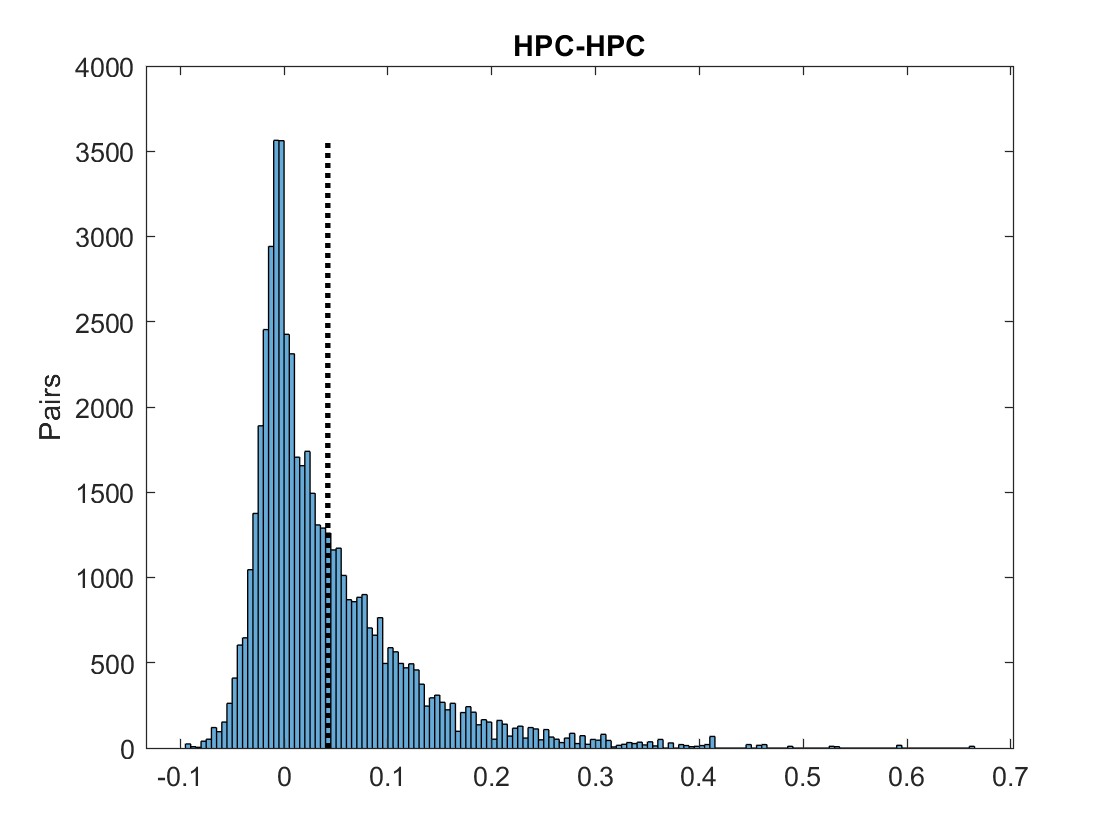

ylabel("Pairs")
title ("HPC-HPC")
example_mean_corr_withhpc = mean_corrwithhpc(1);
example_std_corr_withhpc = std_corrwithhpc(1);

hold on
lineObject=line([example_mean_corr_withhpc,example_mean_corr_withhpc],[0 max(hist_withpfc.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(all_pairs_withpfc)

hist_hp =   Histogram with properties:

             Data: [1×59040 double]
           Values: [1×139 double]
          NumBins: 139
         BinEdges: [1×140 double]
         BinWidth: 0.0050
        BinLimits: [-0.1000 0.5950]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


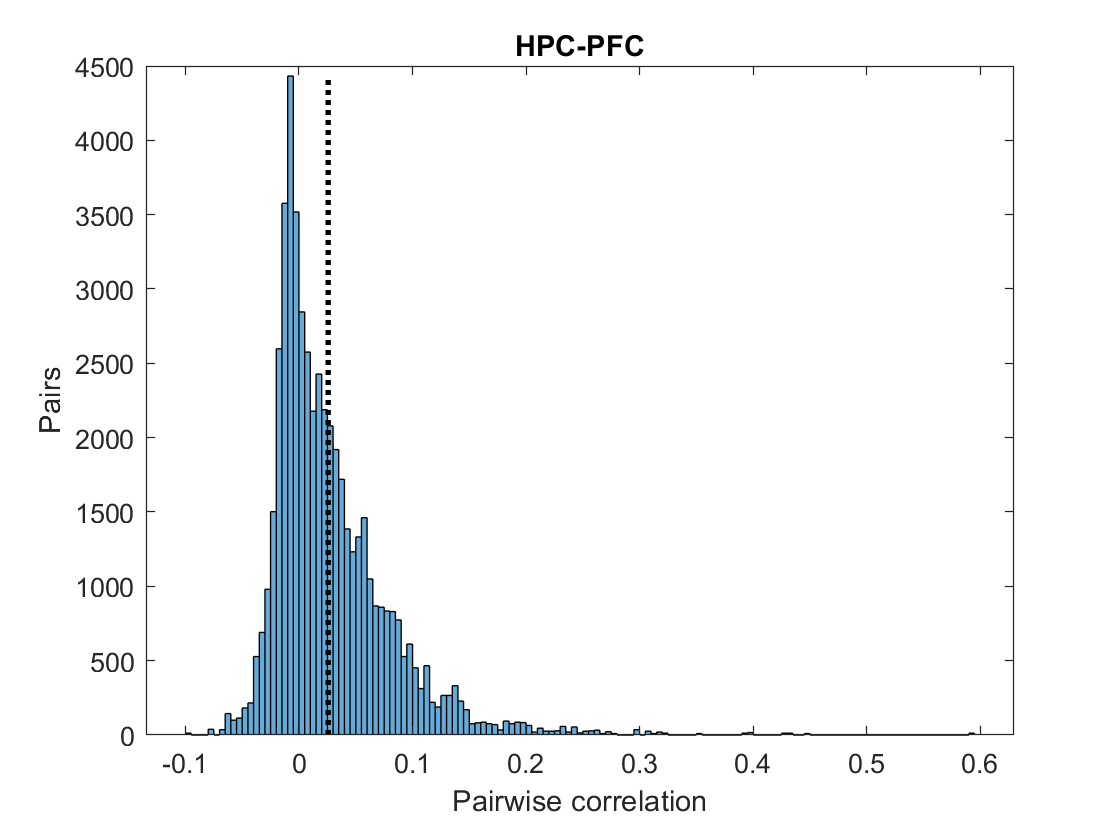

ylabel("Pairs")
title ("HPC-PFC")
example_mean_corr_withpfc = mean_corrwithpfc(1);
example_std_corr_withpfc = std_corrwithpfc(1);

lineObject=line([example_mean_corr_withpfc,example_mean_corr_withpfc],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
xlabel("Pairwise correlation")
linkaxes([ax1,ax2],'x');

[h_corrdiff,p_corrdiff] = kstest2(all_pairs_withpfc,all_pairs_withhpc);

% saving meaningful stats and the corresponding Option fields in a csv
cofiring = table(mean(mean_corrwithhpc), mean(std_corrwithhpc), mean(mean_corrwithpfc), mean(std_corrwithpfc), h_corrdiff, p_corrdiff)

cofiring = 1×6 table
      Var1        Var2        Var3        Var4      h_corrdiff    p_corrdiff
    ________    ________    ________    ________    __________    __________

    0.054736    0.054736    0.057485    0.057485      true        1.813e-131


cofiringRow = table(cofiring, key);

cofiringstats = [cofiringstats; cofiringRow];

save('cofiring', 'cofiringstats')

% print stats
formatSpec1 = "%s: %0.3f±%0.3f";

sprintf(formatSpec1,Patterns(1,1).directionality,mean(mean_corrwithhpc),mean(std_corrwithhpc))

ans = "pfc-pfc: 0.055±0.055"

sprintf(formatSpec1,Patterns(2,1).directionality,mean(mean_corrwithpfc),mean(std_corrwithpfc))

ans = "pfc-pfc: 0.057±0.057"

disp(p_corrdiff)

  1.8130e-131



Average correlation:

HPC-HPC: 0.1413 ± 0.1047

HPC-PFC: 0.0397 ± 0.0509

p < 0.01 for difference between HPC-PFC and HPC-HPC.

*"These weak correlations indicate that only a small fraction of a neuron’s response variability*

*can be explained by another individual neuron"*

#### B: Prediction Performance

load("prediction.mat");
figure(600), clf
% how well a single neuron can predict stuff

single_pred_with_hpc = [];
single_pred_with_pfc = [];

patternPerformance_pfc = zeros(nPatterns, nPartitions); % prediction of
patternPerformance_hpc = zeros(nPatterns, nPartitions);
% useSinglePrediction = true;
for p = 1:nPartitions
    for i = 1:nPatterns
        curr_source = Patterns(p,1,i).X_source';
        nSource = size(curr_source,2);
        for d = 1:2
            curr_target = Patterns(p,d,i).X_target';
            for k = 1:nSource
                curr_singleB = Patterns(p,d,i).rankRegress.singlesource_B{k};
                if ~isempty(curr_singleB)
                    curr_singlesource = curr_source(:,k);
                    [singlepattern,~] = plots.calculatePredictionPerformance(curr_singlesource, curr_target, curr_singleB);
                    if d == 1
                        [single_pred_with_hpc] = [single_pred_with_hpc singlepattern];
                    else
                        [single_pred_with_pfc] = [single_pred_with_pfc singlepattern];
                    end
                end
            end
        end
    end
end
median_singlehh = median(single_pred_with_hpc(~isnan(single_pred_with_hpc)));
temp1 = single_pred_with_pfc(~isinf(single_pred_with_pfc));
temp1 = temp1(~isnan(temp1));
median_singlehp = median(temp1);


r_square_withhpc = [];
r_square_withpfc = [];

r_withhpc_patterns = zeros(nPatterns, nTarget*nPartitions);
r_withpfc_patterns = zeros(nPatterns, nTarget*nPartitions);
% 
% mean_hpcpred_pattern = zeros(1,nPatterns);
% mean_pfcpred_pattern = zeros(1,nPatterns);

for p = 1:10
    for i = 1:nPatterns
        curr_source = (Patterns(p,1,i).X_source)';
        curr_targethpc = (Patterns(p,hpc,i).X_target)';
        curr_targetpfc = (Patterns(p,pfc,i).X_target)';
        
        curr_B_hpc = Patterns(p,hpc,i).rankRegress.B;
        curr_B_pfc = Patterns(p,pfc,i).rankRegress.B;
        
        [patternhpc, meanhpc, ~] = plots.calculatePredictionPerformance(curr_source, curr_targethpc, curr_B_hpc);
        [patternpfc, meanpfc, ~] = plots.calculatePredictionPerformance(curr_source, curr_targetpfc, curr_B_pfc);
        
        r_square_withhpc = [r_square_withhpc patternhpc];
        r_square_withpfc = [r_square_withpfc patternpfc];
        
        patternPerformance_hpc(i,p) = meanhpc;
 
        patternPerformance_pfc(i,p) = meanpfc;
        
        r_withpfc_patterns(i,(p-1)*nTarget+1:p*nTarget) = patternpfc;
        r_withhpc_patterns(i,(p-1)*nTarget+1:p*nTarget) = patternhpc;
        
    end
    
end

% pattern_mean_withhpc = mean(patternPerformance_hpc(~isnan(patternPerformance_hpc)),1);
% pattern_mean_withpfc = mean(patternPerformance_pfc(~isnan(patternPerformance_pfc)),2);

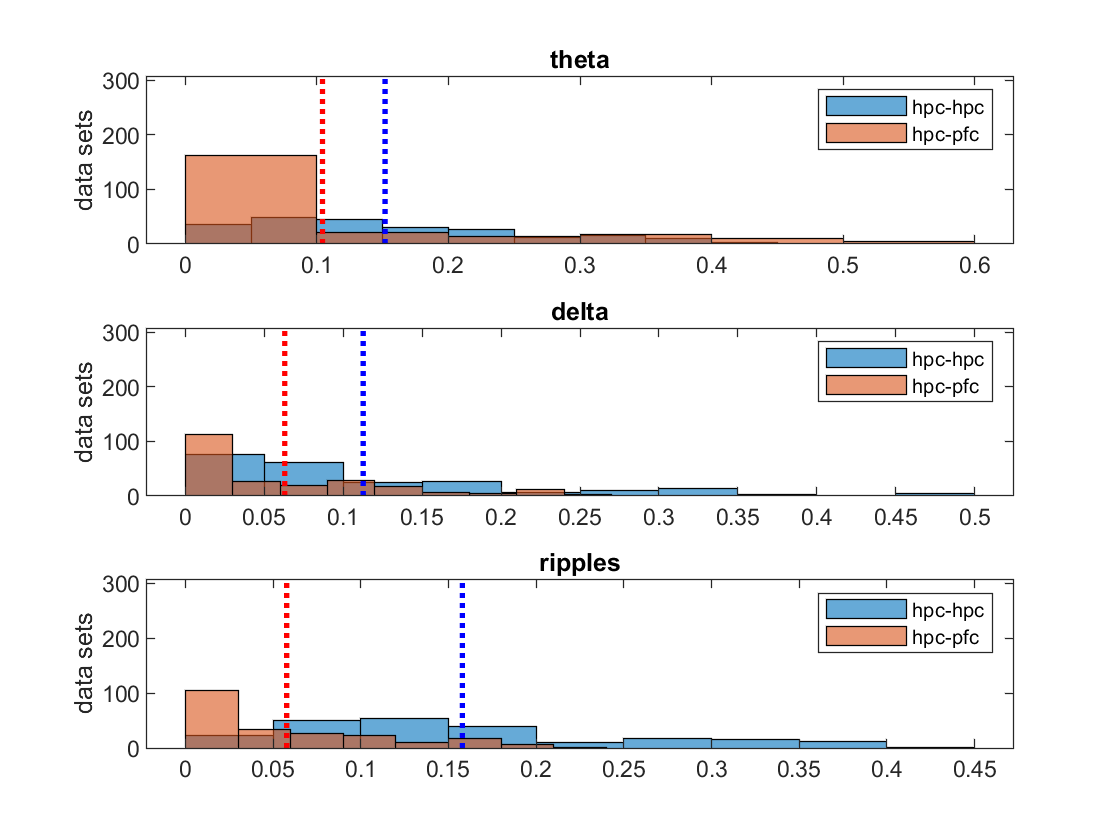

figure(233)
clf
h_pred = zeros(1,nPatterns);
p_pred = zeros(1,nPatterns);
meanpred_hpc = zeros(1,nPatterns);
meanpred_pfc = zeros(1,nPatterns);
for i = 1:nPatterns
    subplot(3,1,i)
    %     curr_hh = r_square_hh_patterns(i,:);
    %     temp_hh = curr_hh(curr_hh~=-10000);
    %     histogram(temp_hh);
    curr1 = r_withhpc_patterns(i,:);
    indices1 = intersect(find(curr1>0), find(~isnan(curr1)));

    histogram(curr1(indices1));
    hold on
    %     curr_hp = r_square_hp_patterns(i,:);
    %     temp_hp = curr_hp(curr_hp~=-10000);
    %     histogram(temp_hp);
    curr2 = r_withpfc_patterns(i,:);
    indices2 = intersect(find(curr2>0), find(~isnan(curr2)));

    histogram(curr2(indices2));
%     histogram(r_withpfc_patterns(i,:));
    
    pattern_mean_withhpc = mean(patternPerformance_hpc(i,:));
    pattern_mean_withpfc = mean(patternPerformance_pfc(i,:));
    meanpred_hpc(i) = pattern_mean_withhpc;
    meanpred_pfc(i) = pattern_mean_withpfc;
    hold on
    avg_hh=line([pattern_mean_withhpc,pattern_mean_withhpc],[0 max(cofiring_hh.Values)]);
    avg_hh.LineStyle = ':'; % Make line dotted
    avg_hh.LineWidth = 2;  % Thicken the line
    avg_hh.Color = 'blue';
    
    hold on
    avg_hp=line([pattern_mean_withpfc,pattern_mean_withpfc],[0 max(cofiring_hh.Values)]);
    avg_hp.LineStyle = ':'; % Make line dotted
    avg_hp.LineWidth = 2;  % Thicken the line
    avg_hp.Color = 'red'; % Color it black
    
    
    [h_pred(i),p_pred(i)] = kstest2(withhpc_pairs(i,:), withpfc_pairs(i,:));
    ylabel("data sets")
    title(patternnames(i));
        if source == "hpc"
        legend("hpc-hpc","hpc-pfc")
    else
        legend("pfc-hpc","pfc-pfc")
        end
end

 [h_hpc, p_hpc] = kstest2(meanpred_hpc, mean_withhpccorr_pattern)

h_hpc = logical
   1


p_hpc = 0.0326

 [h_pfc, p_pfc] = kstest2(meanpred_pfc, mean_withpfccorr_pattern)

h_pfc = logical
   1


p_pfc = 0.0326

mean_withhpc = mean(r_square_withhpc(intersect(~isinf(r_square_withhpc), ~isnan(r_square_withhpc))));
std_withhpc  = std(r_square_withhpc(intersect(~isinf(r_square_withhpc), ~isnan(r_square_withhpc))));

mean_withpfc = mean(r_square_withpfc(intersect(~isinf(r_square_withpfc), ~isnan(r_square_withpfc))));
std_withpfc = std(r_square_withpfc(intersect(~isinf(r_square_withpfc), ~isnan(r_square_withpfc))));

subplot(2,1,1)
ax1 = nexttile;
hist_withpfc = histogram(r_square_withhpc,25)

hist_withpfc =   Histogram with properties:

             Data: [1×720 double]
           Values: [21 36 57 67 54 60 61 53 42 34 35 33 26 23 16 10 9 8 11 1 4 6 4 3 2]
          NumBins: 25
         BinEdges: [0 0.0187 0.0374 0.0561 0.0748 0.0935 0.1122 0.1309 0.1496 0.1683 0.1870 0.2057 0.2244 0.2431 0.2618 0.2805 0.2992 0.3179 0.3366 0.3553 0.3740 0.3927 0.4114 0.4301 0.4488 0.4675]
         BinWidth: 0.0187
        BinLimits: [0 0.4675]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


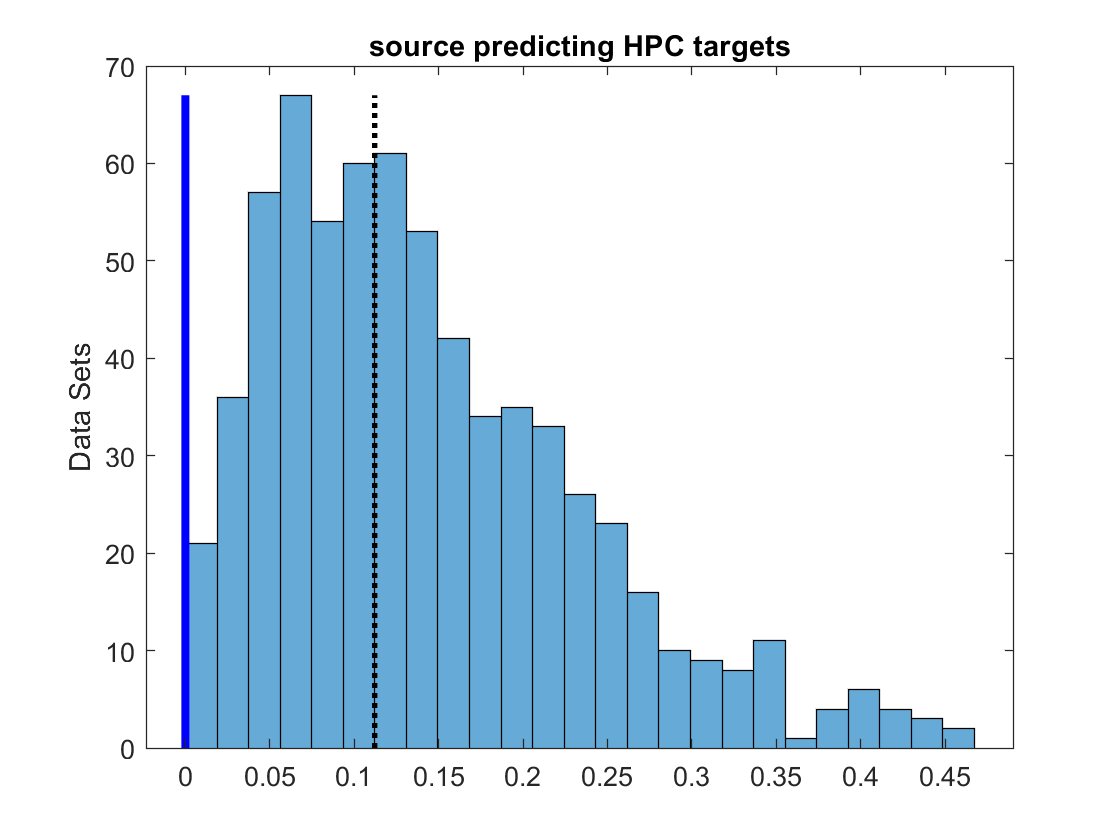

ylabel("Data Sets")
title ("source predicting HPC targets")
lineObject=line([mean_withhpc,mean_withhpc],[0 max(hist_withpfc.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

lineObject2 = line([median_singlehh,median_singlehh],[0 max(hist_withpfc.Values)]);
lineObject2.LineWidth = 3;
lineObject2.Color = 'blue';


subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(r_square_withpfc,25)

hist_hp =   Histogram with properties:

             Data: [1×720 double]
           Values: [160 78 54 58 58 49 30 21 14 17 11 6 17 20 10 15 16 9 2 4 7 3 5 4 2]
          NumBins: 25
         BinEdges: [0 0.0173 0.0346 0.0519 0.0692 0.0865 0.1038 0.1211 0.1384 0.1557 0.1730 0.1903 0.2076 0.2249 0.2422 0.2595 0.2768 0.2941 0.3114 0.3287 0.3460 0.3633 0.3806 0.3979 0.4152 0.4325]
         BinWidth: 0.0173
        BinLimits: [0 0.4325]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


% prediction performance from hpc to pfc cells
ylabel("Data Sets")
title ("source preding PFC targets")
xlabel("Performance")
linkaxes([ax1,ax2],'x');

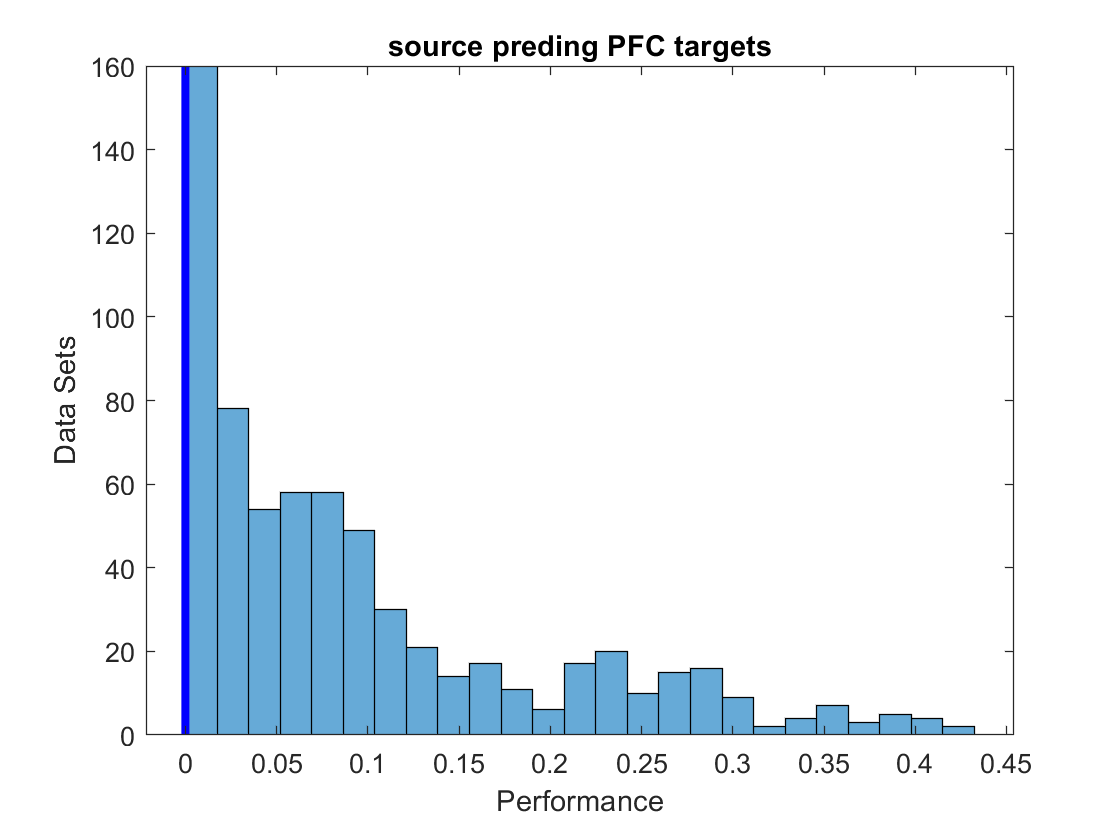

lineObject=line([mean_withpfc,mean_withpfc],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

lineObject2 = line([median_singlehp,median_singlehp],[0 max(hist_hp.Values)]);
lineObject2.LineWidth = 3;  % Thicken the line
lineObject2.Color = 'blue'; % Color it black

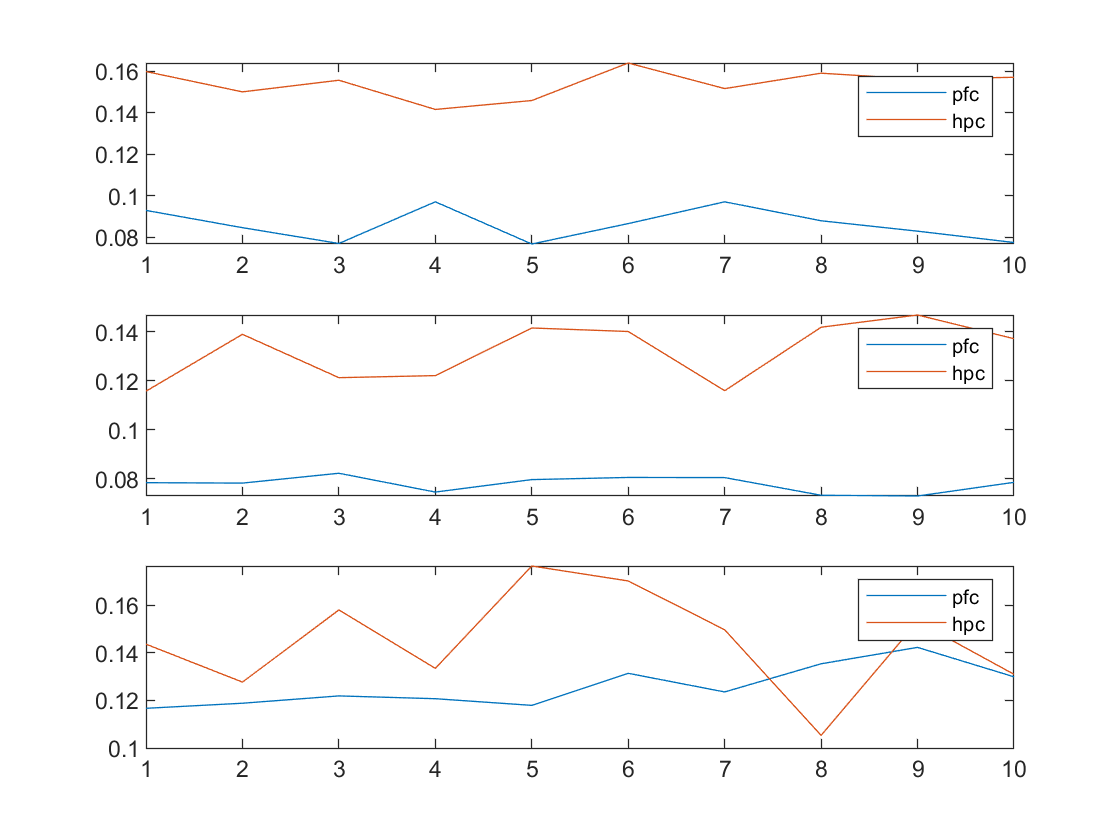

figure(601)
clf
for i = 1:nPatterns
    subplot(3,1,i)
    plot(patternPerformance_pfc(i,:));
    hold on
    plot(patternPerformance_hpc(i,:));
    
    legend("pfc","hpc")
    % how to interpret nans
end


% saving meaningful stats and the corresponding Option fields in a csv
Predictiontable  = table(mean_withhpc, std_withhpc, mean_withpfc, std_withpfc)

Predictiontable = 1×4 table
    mean_hh     std_hh    mean_hp     std_hp
    ________    ______    ________    ______

    0.018957      0       0.026324      0   


predictionRow = table(Predictiontable, key)

predictionRow = 1×2 table
                Predictiontable                    key   
    mean_hh     std_hh    mean_hp     std_hp             
    ________________________________________    _________

    0.018957      0       0.026324      0       "5295fea"


predictionstats = [predictionstats; predictionRow];
save('prediction','predictionstats');


% print stats
formatSpec1 = "%s: %0.3f±%0.3f";
disp("Prediction Performance on Average")

Prediction Performance on Average


sprintf(formatSpec1,Patterns(1,1).directionality,mean_withhpc,std_withhpc)

ans = "hpc-hpc: 0.091±0.102"

sprintf(formatSpec1,Patterns(2,1).directionality,mean_withpfc,std_withpfc)

ans = "hpc-hpc: NaN±NaN"

if useSinglePrediction
    disp('single source prediction median')
    formatSpec2 = "%s: %0.5e";
    sprintf(formatSpec2,Patterns(1,1).directionality,median_singlehh)
    sprintf(formatSpec2,Patterns(1,2).directionality,median_singlehp)
    
end

single source prediction median


ans = "hpc-hpc: -5.32686e-06"

ans = "hpc-pfc: 4.57062e-04"

## Figure 4

numUsedForPrediction = size(curr_target, 2);
% make the averaged version
curr_cvLoss = cell(10,2,3);
for p = 1:10
    for i = 1:nPatterns
        for j = 1:2
            curr_cvLoss{p,j,i} = Patterns(p,j,i).rankRegress.cvLoss;
        end
    end
end

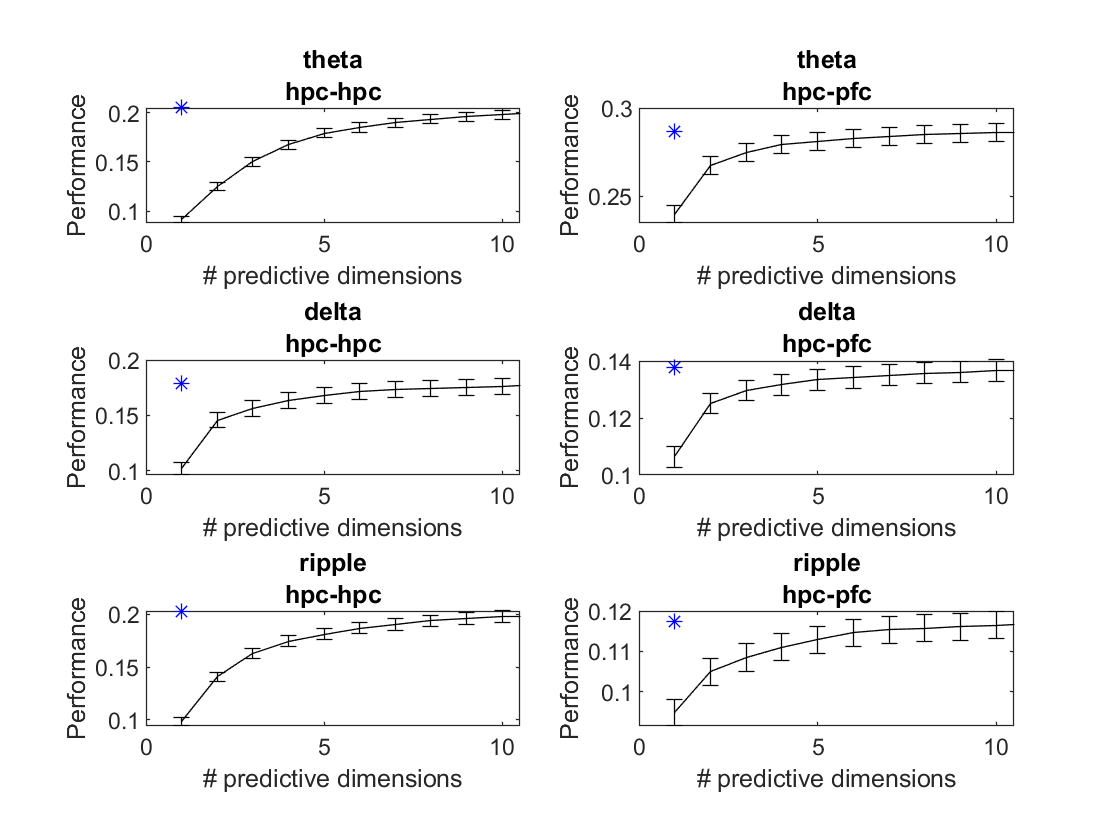

figure(700)
clf
for i = 1:nPatterns
    for j = 1:2
        subplot(3,2,2*(i-1)+j)
        full_model = plots.plotPredictiveDimensions(numUsedForPrediction,curr_cvLoss(:,j,i));
        xlim([0,10.5])
        hold on
        
        plot(1, full_model,'b*');
        
        title([Patterns(p,j,i).name Patterns(p,j,i).directionality])
    end
end

#### 4C

#### How optimal number of predicitive dimensions compare between hpc and pfc (this is gathered over animals)

result = query.getHashed("generateH", "fromFilteredEEG fromRipTimes","sourceArea","CA1")


result =

     []





numResultsToExamine = size(result,1);
ratios = zeros(3,numResultsToExamine);
hpcDims = zeros(3,numResultsToExamine);
pfcDims = zeros(3,numResultsToExamine);

for i = 1:numResultsToExamine
    %     currPatterns = table2array(table2array(result(i,2)));
    %     currPatterns = reshape(currPatterns, [10,2,4]);
    
    load(result(i,:))
    
    temp1 = zeros(3,nPartitions);
    temp2 = zeros(3,nPartitions);
    temp3 = zeros(3,nPartitions);
    for j = 1:nPartitions
        for k = 1:nPatterns
            temp2(k,j) = Patterns(j,hpc,k).rankRegress.optDimReducedRankRegress;
            temp3(k,j) = Patterns(j,pfc,k).rankRegress.optDimReducedRankRegress;
            temp1(k,:) = temp2(k,:)./temp3(k,:);
        end
        
    end
    
    ratios(:,i) = mean(temp1,2);
    hpcDims(:,i) = mean(temp2,2);
    pfcDims(:,i) = mean(temp3,2);
end



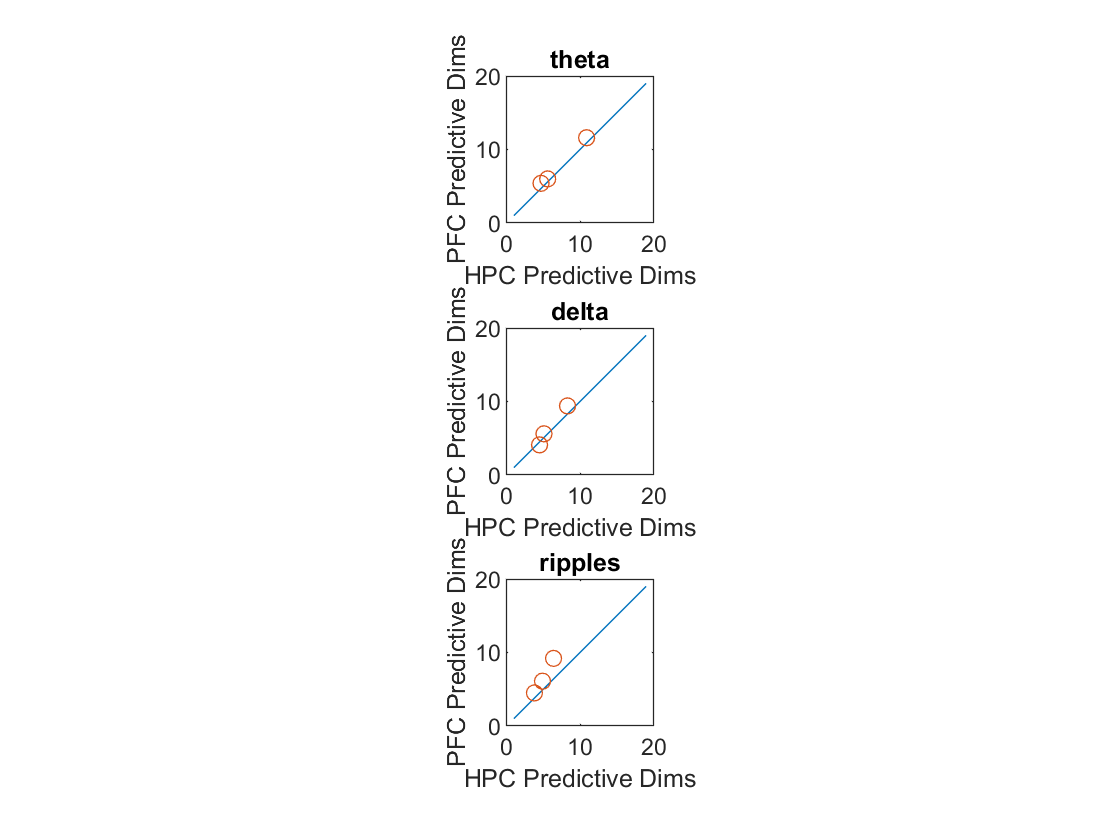


figure(800)

clf
for i = 1:nPatterns
    subplot(3,1,i)
    x = 1:nTarget;
    plot(x,x)
    hold on
    scatter(hpcDims(i,:), pfcDims(i,:));
    ylabel("PFC Predictive Dims")
    xlabel("HPC Predictive Dims")
    title(patternnames(i))
    axis square
end

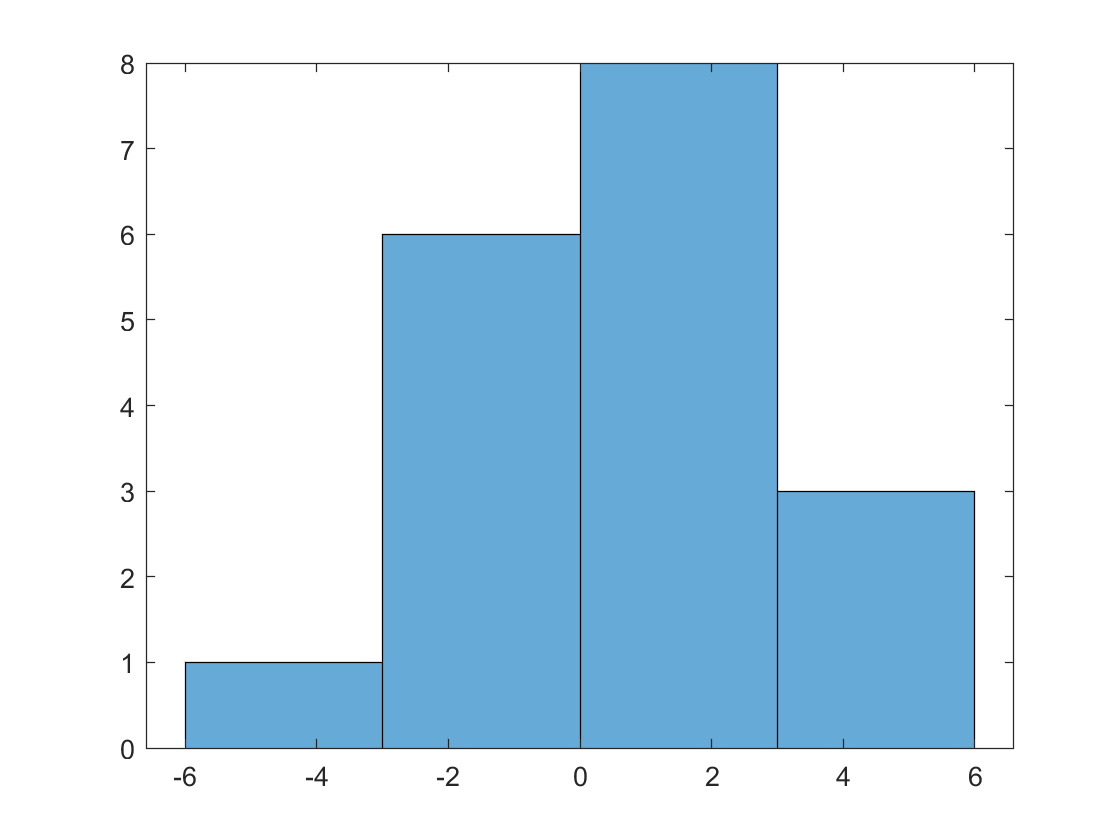

figure (801)
diff = hpcDims-pfcDims;
histogram(diff)

## Figure 5

#### A: (difference in qOpt)